periods = 12*8;
months_arr = 1:periods;
severity = 200;

month_trad_vaccine_ready = Inf;
month_mrna_vaccine_ready = 12;

params = struct();
params.tau_m = 2;
params.tau_o = 8;
params.f_m = 0.3;
params.g_m = 0.4;
params.f_o = 0.3;
params.g_o = 0.4;

cap_avail_low = 2.78;
cap_avail_high = 4.75;
total_pop = 81.3;

[cap_m_low, cap_o_low] = get_pandemic_capacity(months_arr, month_trad_vaccine_ready, ...
                                               month_mrna_vaccine_ready, params, ...
                                               1, 0, cap_avail_low, 0);

[cap_m_high, cap_o_high] = get_pandemic_capacity(months_arr, month_trad_vaccine_ready, ...
                                               month_mrna_vaccine_ready, params, ...
                                               1, 0, cap_avail_high, 0);

vax_fraction_cum_low = cumsum(cap_m_low  / total_pop, 2);
vax_fraction_cum_high = cumsum(cap_m_high / total_pop, 2);

vax_fraction_cum_low(vax_fraction_cum_low > 0.7) = 0.7;
vax_fraction_cum_high(vax_fraction_cum_high > 0.7) = 0.7;

h_low = h(vax_fraction_cum_low);
h_high = h(vax_fraction_cum_high);

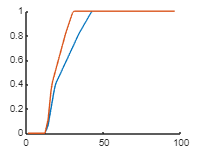

figure; hold on;

plot(months_arr, h_low);
plot(months_arr, h_high);
hold off;


perc_increase = (sum(h_high) - sum(h_low)) ./ sum(h_low);

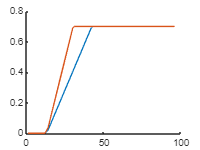

figure; hold on;
plot(months_arr, vax_fraction_cum_low);
plot(months_arr, vax_fraction_cum_high);
hold off;

function [cap_m_arr, cap_o_arr] = get_pandemic_capacity(months_arr, month_trad_vaccine_ready, month_mrna_vaccine_ready, params, ind_m, ind_o, x_m_tau, x_o_tau)
	% mRNA capacity
	cap_m_arr = isbetween(months_arr, month_mrna_vaccine_ready, month_mrna_vaccine_ready + params.tau_m, "openleft") .* (ind_m .* x_m_tau .* params.f_m) + ... % At-risk successful
		(months_arr > month_mrna_vaccine_ready + params.tau_m) .* ind_m .* x_m_tau .* (params.f_m + params.g_m); % At-risk repurposed
	
	% Traditional capacity
	cap_o_arr = isbetween(months_arr, month_trad_vaccine_ready, month_trad_vaccine_ready + params.tau_o, "openleft") .* (ind_o .* x_o_tau .* params.f_o) + ...
		(months_arr > month_trad_vaccine_ready + params.tau_o) .* ind_o .* x_o_tau .* (params.f_o + params.g_o);

end